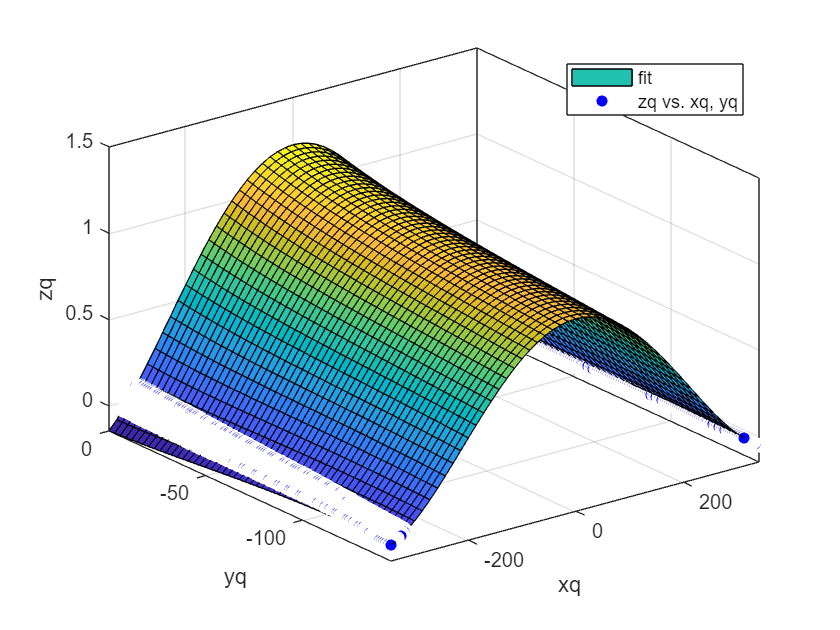

% iidx = data.data.B(:,1) > 0 ;
% X = [-data.data.B(iidx,1);data.data.B(iidx,1)]; 
% Y = [data.data.B(iidx,2);data.data.B(iidx,2)];
% Z = [data.data.B(iidx,3);data.data.B(iidx,3)];

iidx = xq > 0;
X = [-xq(iidx);xq(iidx)]; Y = [yq(iidx);yq(iidx)]; Z = [zq(iidx);zq(iidx)];
% idx =   Y <= max(Y)-2 & Y>= min(Y)+2;
% X = X(idx); Y = Y(idx); Z = Z(idx);
% idx = abs(X) >= 133 & abs(X) <= 139;
% X(idx) = []; Y(idx) = []; Z(idx) = [];
% idx = abs(X) >= 316 & abs(X) <= 319;
% X(idx) = []; Y(idx) = []; Z(idx) = [];
d=1;
% [X,Y,Z] = PreprocessDate([X,Y,Z],d); 
n = 4;%拟合方程次数
[f  gof] = createFit(X, Y, Z, n);

P = coeffvalues(f);%多项式系数向量
s = dispf(P,n,n);
disp(s)

1.2228 + 0.0035789*Y + 2.6281e-05*Y*Y + 1.3401e-07*Y*Y*Y + 2.7531e-10*Y*Y*Y*Y + 1.5058e-17*X + 1.8623e-19*X*Y + 8.0789e-22*X*Y*Y + 3.796e-24*X*Y*Y*Y + -1.8243e-05*X*X + -3.4357e-08*X*X*Y + -9.4816e-11*X*X*Y*Y + -1.5434e-22*X*X*X + -1.4272e-24*X*X*X*Y + 5.6357e-11*X*X*X*X 


disp(gof)

           sse: 0.1779
       rsquare: 0.9932
           dfe: 32173
    adjrsquare: 0.9932
          rmse: 0.0024



%保存拟合结果到文本
% c2 = cell2mat(struct2cell(gof));
% a = {s;c2};
% fileID = fopen(strcat(fileparts(filepath),'poly.txt'),'w');%%fileparts提取文件路径
% formatSpec = '%s %d %2.1f %s\n';
% [nrows,ncols] = size(a);
% for row = 1:nrows
%     fprintf(fileID,formatSpec,a{row,:}); % 注意此处不用{}，而是（）时，得到的字符串有引号，需注意
% end
% fclose(fileID);
